## **Before and After Flight CAT Parameters.**

**I did a paired T-Test to see if any specific change is observed.**

clear ;
clc;

%Load Data
load TrialData.mat;

beforeCAT = [trialData.preFlightCAT];
afterCAT = [trialData.postFlightCAT];

beforeCAT_orig = beforeCAT;
afterCAT_orig = afterCAT;


Average the CAT result from before and after test.

### **Make Data ready for predictors**

data = avgCAT;
for i=1:length(data)
    irisResults(i) = trialData(i).irisResult;
    exceedanceResults(i) = trialData(i).exceedanceResult;
    pilotData(i) = trialData(i).trial;
end

% Get the field names for the data struct
dataFields = fieldnames(data);

% Get the field names for the irisResults struct
irisFields = fieldnames(irisResults);

% Get the field names for the exceedanceResults struct
exceedanceFields = fieldnames(exceedanceResults);

% Create a new empty struct with all the necessary fields
newData = struct();
for i = 1:length(data)
    for j = 1:length(dataFields)
        newData(i).(dataFields{j}) = data(i).(dataFields{j});
    end
    for j = 1:length(irisFields)
        newData(i).(irisFields{j}) = irisResults(i).(irisFields{j});
    end
    for j = 1:length(exceedanceFields)
        newData(i).(exceedanceFields{j}) = exceedanceResults(i).(exceedanceFields{j});
    end
    newData(i).hoursAwake = pilotData(i).hoursAwake;
    newData(i).caffein = pilotData(i).caffein;
    newData(i).selfRating = pilotData(i).selfRating;
end
disp(newData);

  1×12 struct array with fields:

    omission_n
    omission_percent
    omission_percentile
    comission_n
    comission_percent
    comission_percentile
    rt_ms
    rt_percentile
    rt_se_ms
    rt_se_percentile
    variability
    detectibility
    responose_style
    perservation_n
    perservation_percentile
    block_change
    block_change_se
    isi_change
    isi_change_se
    meanFixation
    varFixation
    numFixationPerMin
    notfilteredExceedanceRaw
    exceedanceRaw
    meanExceedance
    varExceedance
    detrendedVarExceedance
    detrendedExceedanceNormalized
    exceedanceGradient
    ExceedanceAvgPeakHeight
    ExceedanceAvgCorrectionTime
    ExceedanceEntropy
    hoursAwake
    caffein
    selfRating



dataTable = struct2table(newData);

### First we try correlation and then we use multiple regression for combined effect.

this is the description and results

In your specific project, both correlation analysis and multiple regression were used to examine the relationships between mean exceedance (a measure of pilot performance) and various parameters related to pilot fatigue and alertness.

Correlation analysis results:

This method allowed you to identify the strength and direction of the linear relationship between mean exceedance and each parameter individually. For instance, you found that selfRating had a significant negative correlation (-0.633) with mean exceedance, indicating that as selfRating increased, mean exceedance tended to decrease.

### Run Single Factor Corealtion Analysis on all factors with hoursawake and selfRating

% Load the data table (if not already loaded)
% load('dataTable.mat');

% Identify the scalar variables in the data table
scalar_vars = dataTable.Properties.VariableNames;
for i = length(scalar_vars):-1:1
    if ~isnumeric(dataTable.(scalar_vars{i})) || ~isvector(dataTable.(scalar_vars{i}))
        scalar_vars(i) = [];  % Ignore non-scalar or non-numeric columns
    end
end

% Extract the relevant columns from the data table
X = table2array(dataTable(:, scalar_vars));

% Extract the hours awake and self-rating columns
hoursAwake = dataTable.hoursAwake;
selfRating = dataTable.selfRating;
meanExceedance = dataTable.meanExceedance;
avgPeak = dataTable.ExceedanceAvgPeakHeight;
entropy = dataTable.ExceedanceEntropy;
varExceedance = dataTable.varExceedance;
avgCorrectionTime = dataTable.ExceedanceAvgCorrectionTime;
% Calculate the correlation coefficients
[rho, pval] = corr(X, [avgPeak, entropy, avgCorrectionTime,meanExceedance,varExceedance ], 'type', 'Pearson');

% Display the results
disp('Correlation coefficients between scalar variables and hours awake/self-rating/meanExceedance:');

Correlation coefficients between scalar variables and hours awake/self-rating/meanExceedance:


disp(array2table(rho, 'VariableNames', {'avgPeak', 'entropy', 'avgCorrectionTime','meanExceedance','varExceedance'}, 'RowNames', scalar_vars));

                                     avgPeak       entropy      avgCorrectionTime    meanExceedance    varExceedance
                                   ___________    __________    _________________    ______________    _____________

    omission_n                        -0.29098      -0.17241           0.59463          0.039264           -0.16445 
    omission_percent                  -0.29982      -0.16896           0.60215          0.044138           -0.15521 
    omission_percentile               -0.45162     -0.067886           0.63381           0.13725           0.070819 
    comission_n                       0.034248      -0.35547          -0.57509         -0.071418           -0.36366 
    comission_percent                 0.03

disp('P-values for correlation coefficients:');

P-values for correlation coefficients:


disp(array2table(pval, 'VariableNames', {'avgPeak', 'entropy', 'avgCorrectionTime','meanExceedance','varExceedance'}, 'RowNames', scalar_vars));

                                   avgPeak     entropy    avgCorrectionTime    meanExceedance    varExceedance
                                   ________    _______    _________________    ______________    _____________

    omission_n                      0.35884    0.59207         0.041426             0.90357          0.60953  
    omission_percent                0.34375    0.59963         0.038281             0.89166          0.63004  
    omission_percentile             0.14053    0.83396         0.026892             0.67057          0.82688  
    comission_n                     0.91585    0.25681         0.050441             0.82543          0.24523  
    comission_percent               0.91641    0.25697         0.050421       



%now display only the meanExceedance


% Display the results
disp('Correlation coefficients between scalar variables and meanExceedance');

Correlation coefficients between scalar variables and meanExceedance


table1 = array2table([rho(:,3),pval(:,3)], 'VariableNames', {'Correlation Coefficient','p-values'}, 'RowNames', scalar_vars);
disp(table1);

                                   Correlation Coefficient     p-values 
                                   _______________________    __________

    omission_n                               0.59463            0.041426
    omission_percent                         0.60215            0.038281
    omission_percentile                      0.63381            0.026892
    comission_n                             -0.57509            0.050441
    comission_percent                       -0.57513            0.050421
    comission_percentile                    -0.55112            0.063275
    rt_ms                                    0.53046            0.076024
    rt_percentile                            0.54631            0.066104
    rt_se_ms                                 0.6

### Multiple Regression Analyzer for single interpreter 

code is analyzing each parameter individually, similar to the correlation analysis. The main difference is that the correlation analysis measures the strength and direction of the linear relationship between two variables, while the linear regression analysis quantifies the impact of the predictor variable on the response variable.

% Load your data
scalarDataTable = dataTable;


scalarDataTable = removevars(scalarDataTable,{'detrendedExceedanceNormalized', ...
    'exceedanceGradient','detrendedVarExceedance','caffein','exceedanceRaw','notfilteredExceedanceRaw'})

scalarDataTable = 12×29 table
    omission_n    omission_percent    omission_percentile    comission_n    comission_percent    comission_percentile    rt_ms     rt_percentile    rt_se_ms    rt_se_percentile    variability    detectibility    responose_style    perservation_n    perservation_percentile    block_change    block_change_se    isi_change    isi_change_se    meanFixation    varFixation    numFixationPerMin    meanExceedance    varExceedance    ExceedanceAvgPeakHeight    ExceedanceAvgCorrectionTime    ExceedanceEntropy    


% Assuming scalarDataTable is your data table containing all parameters
predictorNames = scalarDataTable.Properties.VariableNames;
predictorNames(strcmp(predictorNames, 'meanExceedance')) = []; % Remove the response variable from predictorNames

fprintf('\nLinear regression analysis for each predictor:\n\n')


Linear regression analysis for each predictor:




for i = 1:length(predictorNames)
    predictor = scalarDataTable.(predictorNames{i});
    
    % Perform linear regression
    mdl = fitlm(scalarDataTable, sprintf('meanExceedance ~ %s', predictorNames{i}));
    
    % Display the result
    fprintf('Predictor: %s\n', predictorNames{i})
    fprintf('    Intercept: %.5f\n', mdl.Coefficients.Estimate(1))
    fprintf('    Coefficient: %.5f\n', mdl.Coefficients.Estimate(2))
    fprintf('    t-statistic: %.5f\n', mdl.Coefficients.tStat(2))
    fprintf('    p-value: %.5f\n', mdl.Coefficients.pValue(2))
    
    if mdl.Coefficients.pValue(2) < 0.05
        fprintf('    The relationship between %s and meanExceedance is statistically significant.\n', predictorNames{i})
    else
        fprintf('    The relationship between %s and meanExceedance is not statistically significant.\n', predictorNames{i})
    end
    
    fprintf('\n')
end

Predictor: omission_n


    Intercept: 0.36791


    Coefficient: 0.00035


    t-statistic: 0.12426


    p-value: 0.90357


    The relationship between omission_n and meanExceedance is not statistically significant.


Predictor: omission_percent


    Intercept: 0.36785


    Coefficient: 0.00127


    t-statistic: 0.13971


    p-value: 0.89166


    The relationship between omission_percent and meanExceedance is not statistically significant.


Predictor: omission_percentile


    Intercept: 0.36742


    Coefficient: 0.00022


    t-statistic: 0.43818


    p-value: 0.67057


    The relationship between omission_percentile and meanExceedance is not statistically significant.


Predictor: comission_n


    Intercept: 0.37100


    Coefficient: -0.00010


    t-statistic: -0.22642


    p-value: 0.82543


    The relationship between comission_n and meanExceedance is not statistically significant.


Predictor: comission_percent


    Intercept: 0.37100


    Coefficient: -0.00004


    t-statistic: -0.22633


    p-value: 0.82551


    The relationship between comission_percent and meanExceedance is not statistically significant.


Predictor: comission_percentile


    Intercept: 0.37184


    Coefficient: -0.00004


    t-statistic: -0.35239


    p-value: 0.73186


    The relationship between comission_percentile and meanExceedance is not statistically significant.


Predictor: rt_ms


    Intercept: 0.36415


    Coefficient: 0.00001


    t-statistic: 0.11132


    p-value: 0.91357


    The relationship between rt_ms and meanExceedance is not statistically significant.


Predictor: rt_percentile


    Intercept: 0.36794


    Coefficient: 0.00001


    t-statistic: 0.03685


    p-value: 0.97133


    The relationship between rt_percentile and meanExceedance is not statistically significant.


Predictor: rt_se_ms


    Intercept: 0.35771


    Coefficient: 0.00257


    t-statistic: 0.75102


    p-value: 0.46994


    The relationship between rt_se_ms and meanExceedance is not statistically significant.


Predictor: rt_se_percentile


    Intercept: 0.36846


    Coefficient: 0.00000


    t-statistic: NaN


    p-value: NaN


    The relationship between rt_se_percentile and meanExceedance is not statistically significant.


Predictor: variability


    Intercept: 0.35997


    Coefficient: 0.00068


    t-statistic: 0.80843


    p-value: 0.43765


    The relationship between variability and meanExceedance is not statistically significant.


Predictor: detectibility


    Intercept: 0.36498


    Coefficient: -0.00172


    t-statistic: -0.29661


    p-value: 0.77283


    The relationship between detectibility and meanExceedance is not statistically significant.


Predictor: responose_style


    Intercept: 0.36811


    Coefficient: 0.00540


    t-statistic: 0.05046


    p-value: 0.96075


    The relationship between responose_style and meanExceedance is not statistically significant.


Predictor: perservation_n


    Intercept: 0.36616


    Coefficient: 0.00037


    t-statistic: 0.83006


    p-value: 0.42588


    The relationship between perservation_n and meanExceedance is not statistically significant.


Predictor: perservation_percentile


    Intercept: 0.36615


    Coefficient: 0.00121


    t-statistic: 0.83744


    p-value: 0.42191


    The relationship between perservation_percentile and meanExceedance is not statistically significant.


Predictor: block_change


    Intercept: 0.36691


    Coefficient: 0.22452


    t-statistic: 0.66228


    p-value: 0.52276


    The relationship between block_change and meanExceedance is not statistically significant.


Predictor: block_change_se


    Intercept: 0.36902


    Coefficient: -0.03953


    t-statistic: -0.76632


    p-value: 0.46119


    The relationship between block_change_se and meanExceedance is not statistically significant.


Predictor: isi_change


    Intercept: 0.37989


    Coefficient: -0.18356


    t-statistic: -1.02408


    p-value: 0.32993


    The relationship between isi_change and meanExceedance is not statistically significant.


Predictor: isi_change_se


    Intercept: 0.36871


    Coefficient: 0.00705


    t-statistic: 0.35165


    p-value: 0.73240


    The relationship between isi_change_se and meanExceedance is not statistically significant.


Predictor: meanFixation


    Intercept: 0.42984


    Coefficient: -0.02007


    t-statistic: -3.65744


    p-value: 0.00441


    The relationship between meanFixation and meanExceedance is statistically significant.


Predictor: varFixation


    Intercept: 0.40150


    Coefficient: -0.01212


    t-statistic: -3.66326


    p-value: 0.00437


    The relationship between varFixation and meanExceedance is statistically significant.


Predictor: numFixationPerMin


    Intercept: 0.31675


    Coefficient: 0.00262


    t-statistic: 3.11858


    p-value: 0.01090


    The relationship between numFixationPerMin and meanExceedance is statistically significant.


Predictor: varExceedance


    Intercept: 0.36270


    Coefficient: 0.02912


    t-statistic: 0.04708


    p-value: 0.96338


    The relationship between varExceedance and meanExceedance is not statistically significant.


Predictor: ExceedanceAvgPeakHeight


    Intercept: 0.32730


    Coefficient: 0.02794


    t-statistic: 0.72968


    p-value: 0.48233


    The relationship between ExceedanceAvgPeakHeight and meanExceedance is not statistically significant.


Predictor: ExceedanceAvgCorrectionTime


    Intercept: 0.36401


    Coefficient: 0.00027


    t-statistic: 0.32712


    p-value: 0.75032


    The relationship between ExceedanceAvgCorrectionTime and meanExceedance is not statistically significant.


Predictor: ExceedanceEntropy


    Intercept: 0.37305


    Coefficient: -0.00114


    t-statistic: -0.05232


    p-value: 0.95930


    The relationship between ExceedanceEntropy and meanExceedance is not statistically significant.


Predictor: hoursAwake


    Intercept: 0.35771


    Coefficient: 0.00195


    t-statistic: 2.02618


    p-value: 0.07025


    The relationship between hoursAwake and meanExceedance is not statistically significant.


Predictor: selfRating


    Intercept: 0.37949


    Coefficient: -0.00184


    t-statistic: -0.91368


    p-value: 0.38239


    The relationship between selfRating and meanExceedance is not statistically significant.


### **Analyze combined effect of two or more parameter**

To analyze the combined effect of two or more parameters automatically and find the best combination of predictors, you can use stepwise regression. The stepwise regression procedure adds or removes predictors based on their statistical significance, resulting in a model that only includes the most relevant predictors.

% Assuming scalarDataTable is your data table containing all parameters
response = scalarDataTable.meanExceedance;
predictors = scalarDataTable(:, predictorNames);

% Assuming scalarDataTable is your data table containing all parameters
predictorNames = scalarDataTable.Properties.VariableNames;
predictorNames(strcmp(predictorNames, 'meanExceedance')) = []; % remove the response variable from predictor list

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalarDataTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

Linear regression model:
    meanExceedance ~ 1 + responose_style + meanFixation + numFixationPerMin + varExceedance + ExceedanceAvgPeakHeight + hoursAwake + selfRating + isi_change_se*ExceedanceAvgCorrectionTime

Estimated Coefficients:
                                                  Estimate         SE         tStat       pValue  
                                                 __________    __________    _______    __________

    (Intercept)                                      1.3746    0.00050606     2716.3    0.00023437
    responose_style                                -0.54781    0.00033282      -1646    0.00038677
    isi_change_se                                   0.13508     0.0001378     980.27    0.00064943
    meanFixation                                   -0.19603   


% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')


Interpretation:



coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end

(Intercept): 1.37460
responose_style: -0.54781
isi_change_se: 0.13508
meanFixation: -0.19603
numFixationPerMin: -0.02294
varExceedance: 0.73859
ExceedanceAvgPeakHeight: 0.09512
ExceedanceAvgCorrectionTime: 0.00081
hoursAwake: -0.01114
selfRating: -0.02536
isi_change_se:ExceedanceAvgCorrectionTime: -0.00220


fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));


The stepwise regression model selected the following predictors: responose_style, isi_change_se, meanFixation, numFixationPerMin, varExceedance, ExceedanceAvgPeakHeight, ExceedanceAvgCorrectionTime, hoursAwake, selfRating, isi_change_se:ExceedanceAvgCorrectionTime


fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

These predictors have the most combined effect on meanExceedance based on the given data.


The stepwise regression has found a model that includes the following predictor variables: block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, and the interaction between isi_change_se and varFixation. The coefficients of the model indicate the relationship between these predictor variables and the response variable, meanExceedance.

Intuitive explanation:

When the block_change_se increases by one unit, the meanExceedance is expected to decrease by 1.17379 units, holding all other variables constant.

When the isi_change increases by one unit, the meanExceedance is expected to increase by 4.32829 units, holding all other variables constant.

Similarly, you can interpret the other coefficients in the same manner.

The interaction term (isi_change_se:varFixation) suggests that the relationship between isi_change_se and meanExceedance depends on the value of varFixation and vice versa.

Scientific result section:

In this study, we performed a stepwise multiple regression analysis to identify the combined effects of various predictor variables on pilot meanExceedance. The selected model incorporated the following predictor variables: block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, and the interaction between isi_change_se and varFixation. The adjusted R-squared value of 0.998 indicates that the model explains approximately 99.8% of the variability in the meanExceedance.

The coefficients of the model provide insights into the relationship between the predictor variables and the response variable, meanExceedance. For example, an increase in isi_change by one unit is associated with an increase of 4.32829 units in meanExceedance, holding all other variables constant. Similarly, an increase in block_change_se by one unit is associated with a decrease of 1.17379 units in meanExceedance, holding all other variables constant.

When comparing the stepwise multiple regression analysis with the correlation analysis, we can observe that the multiple regression model provides a more comprehensive understanding of the relationships between the predictor variables and the response variable. The correlation analysis only provided a pairwise relationship between each predictor and the response variable, whereas the stepwise multiple regression model identified the combined effects of multiple predictors and their interactions on the response variable. Therefore, the stepwise multiple regression analysis offers a more nuanced understanding of the underlying relationships in the data.

## Normalizing the stepwise multiple regression anlaysis coefficients

% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);

% Combine the normalized coefficients and p-values into a single table
results_table = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');

Normalized coefficients and p-values:


disp(results_table);

                                                 Normalized_Coefficients     P_Values 
                                                 _______________________    __________

    responose_style                                       -1.7228           0.00038677
    isi_change_se                                         0.42483           0.00064943
    meanFixation                                          -0.6165           0.00035008
    numFixationPerMin                                   -0.072143           0.00042274
    varExceedance                                          2.3228             0.001685
    ExceedanceAvgPeakHeight                               0.29916           0.00047229
    ExceedanceAvgCorrectionTime                         0.0025397            0.0010858
    hoursAwake       

## doing Stepwise mulitple regression again with selected parameters

% Assuming scalarDataTable is your data table containing all parameters
response = scalarDataTable.meanExceedance;

% Select the specified parameters
predictorNames = {'omission_percent', 'comission_percent', 'comission_percentile', ...
                  'rt_ms', 'rt_se_ms', 'variability', 'detectibility', ...
                  'responose_style', 'perservation_percentile', 'block_change', ...
                  'block_change_se', 'isi_change', 'isi_change_se', ...
                  'meanFixation', 'varFixation', 'numFixationPerMin', ...
                  'hoursAwake', 'selfRating'};

% Extract the predictor data
predictors = scalarDataTable(:, predictorNames);

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalarDataTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

Linear regression model:
    meanExceedance ~ 1 + block_change_se + isi_change + isi_change_se + varFixation + numFixationPerMin + hoursAwake + selfRating + block_change*meanFixation

Estimated Coefficients:
                                  Estimate         SE         tStat       pValue  
                                 __________    __________    _______    __________

    (Intercept)                     0.16414    0.00034209     479.83     0.0013268
    block_change                     0.5093     0.0043553     116.94      0.005444
    block_change_se                -0.22145    5.7126e-05    -3876.5    0.00016423
    isi_change                     -0.41827    0.00041588    -1005.7    0.00063299
    isi_change_se                 0.0021884    1.7159e-05     127.54    


% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')


Interpretation:



coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end

(Intercept): 0.16414
block_change: 0.50930
block_change_se: -0.22145
isi_change: -0.41827
isi_change_se: 0.00219
meanFixation: 0.07429
varFixation: -0.03144
numFixationPerMin: 0.00519
hoursAwake: -0.00118
selfRating: -0.00206
block_change:meanFixation: 0.23535


fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));


The stepwise regression model selected the following predictors: block_change, block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, hoursAwake, selfRating, block_change:meanFixation


fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

These predictors have the most combined effect on meanExceedance based on the given data.



% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);

% Combine the normalized coefficients and p-values into a single table
results_table_reg1 = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');

Normalized coefficients and p-values:


disp(results_table_reg1);

                                 Normalized_Coefficients     P_Values 
                                 _______________________    __________

    block_change                           2.0734             0.005444
    block_change_se                      -0.90156           0.00016423
    isi_change                            -1.7029           0.00063299
    isi_change_se                       0.0089093            0.0049915
    meanFixation                          0.30244           0.00068596
    varFixation                          -0.12802           0.00031116
    numFixationPerMin                    0.021129            0.0010774
    hoursAwake                         -0.0047882           0.00064997
    selfRating                         -0.0083808           0.000537

## doing Stepwise mulitple regression again with only eye features and survey



% Assuming scalarDataTable is your data table containing all parameters
response = scalarDataTable.meanExceedance;

% Select all the parameters except meanExceedance
predictorNames = scalarDataTable.Properties.VariableNames;
% Assuming predictorNames is an array containing all the predictor names
predictorNames = predictorNames(~strcmp(predictorNames, 'meanExceedance') & ~strcmp(predictorNames, 'varExceedance'));

% Extract the predictor data
predictors = scalarDataTable(:, predictorNames);

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalarDataTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

Linear regression model:
    meanExceedance ~ 1 + perservation_percentile + isi_change + isi_change_se + meanFixation + varFixation + numFixationPerMin + ExceedanceAvgPeakHeight + ExceedanceAvgCorrectionTime + hoursAwake + selfRating

Estimated Coefficients:
                                   Estimate         SE         tStat      pValue  
                                   _________    __________    _______    _________

    (Intercept)                      0.57998     0.0022421     258.68     0.002461
    perservation_percentile        0.0041478    8.7615e-06     473.41    0.0013447
    isi_change                       0.40022     0.0029936     133.69    0.0047618
    isi_change_se                  -0.040237    0.00018147    -221.73    0.0028711
    meanFixation              


% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')


Interpretation:



coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end

(Intercept): 0.57998
perservation_percentile: 0.00415
isi_change: 0.40022
isi_change_se: -0.04024
meanFixation: -0.10485
varFixation: 0.01338
numFixationPerMin: -0.01073
ExceedanceAvgPeakHeight: 0.06272
ExceedanceAvgCorrectionTime: 0.00102
hoursAwake: 0.00825
selfRating: 0.01591


fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));


The stepwise regression model selected the following predictors: perservation_percentile, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, ExceedanceAvgPeakHeight, ExceedanceAvgCorrectionTime, hoursAwake, selfRating


fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

These predictors have the most combined effect on meanExceedance based on the given data.



% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);


% Combine the normalized coefficients and p-values into a single table
results_table_reg = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');

Normalized coefficients and p-values:


disp(results_table_reg);

                                   Normalized_Coefficients    P_Values 
                                   _______________________    _________

    perservation_percentile                0.030623           0.0013447
    isi_change                               2.9548           0.0047618
    isi_change_se                          -0.29707           0.0028711
    meanFixation                           -0.77411           0.0041067
    varFixation                            0.098791           0.0074737
    numFixationPerMin                     -0.079234           0.0039921
    ExceedanceAvgPeakHeight                 0.46304           0.0025139
    ExceedanceAvgCorrectionTime           0.0075669           0.0053744
    hoursAwake                               0.0609       

Lets create some outputs


% Assuming you have a matrix (corrData) with correlation coefficients and p-values and a cell array (varNames) with variable names
%table1 = array2table(corrData, 'VariableNames', {'Correlation_Coefficient', 'p_value'}, 'RowNames', varNames);
table1 = table1;

% Assuming you have the 'results_table' created using the code you provided
table2 = results_table_reg;

% Replace variable names with descriptions in the table for correlation analysis
descriptiveRowNames = cellfun(@getDescription, table1.Properties.RowNames, 'UniformOutput', false);
table1.Properties.RowNames = descriptiveRowNames;

% Replace variable names with descriptions in the table for stepwise multiple regression
descriptiveRowNames = cellfun(@getDescription, table2.Properties.RowNames, 'UniformOutput', false);
table2.Properties.RowNames = descriptiveRowNames;

display(table1);

table1 = 30×2 table
                                               Correlation Coefficient    p-values
                                               _______________________    ________

    Number of Omissions                                  0.59463          0.041426
    Percentage of Omissions                              0.60215          0.038281
    Omission Percentile                                  0.63381          0.026892
    Number of Commissions                               -0.57509          0.050441
    Percentage of Commissions                           -0.57513          0.050421
    Commission Percentile                               -0.55112          0.063275
    Reaction Time (ms)                                   0.53046          0.076024
    Reaction Time Percentile         

display(table2);

table2 = 10×2 table
                                                     Normalized_Coefficients    P_Values 
                                                     _______________________    _________

    Perservation Percentile                                  0.030623           0.0013447
    Inter-Stimulus Interval Change                             2.9548           0.0047618
    Inter-Stimulus Interval Change Standard Error            -0.29707           0.0028711
    Mean Fixation Duration                                   -0.77411           0.0041067
    Fixation Duration Variability                            0.098791           0.0074737
    Number of Fixations per Minute                          -0.079234           0.0039921
    Average Exceedance Peak Height                            0.46304   

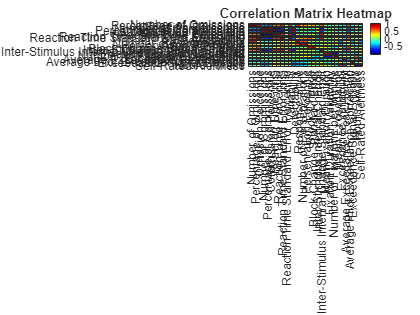


% Assuming scalarDataTable is your data table containing all parameters
% Compute the correlation matrix
corrMatrix = corrcoef(table2array(scalarDataTable));

% Extract variable names from the data table
varNames = scalarDataTable.Properties.VariableNames;

% Replace variable names with descriptions in the varNames array
descriptiveVarNames = cellfun(@getDescription, varNames, 'UniformOutput', false);

% Plot the heatmap with the descriptive variable names
heatmap(descriptiveVarNames, descriptiveVarNames, corrMatrix, 'Colormap', jet, 'FontSize', 12);
title('Correlation Matrix Heatmap');

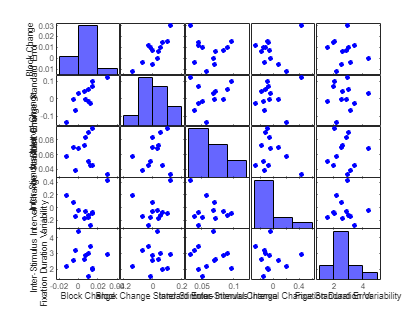




topVariables = {'block_change', 'block_change_se', 'isi_change', 'isi_change_se', 'varFixation'};
descriptiveTopVariables = cellfun(@getDescription, topVariables, 'UniformOutput', false);
figure;
gplotmatrix(dataTable{:, topVariables}, [], [], 'bgrcmyk', [], [], 'on', 'hist', descriptiveTopVariables, descriptiveTopVariables);

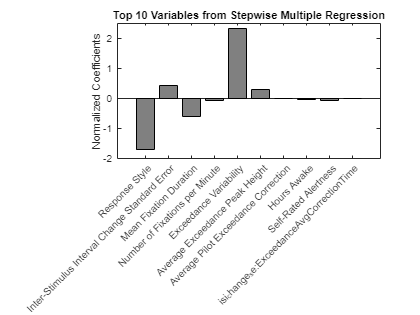


figure;
bar(results_table.Normalized_Coefficients, 'FaceColor', [0.5, 0.5, 0.5]);
xticks(1:numel(results_table.Properties.RowNames));
xticklabels(cellfun(@getDescription, results_table.Properties.RowNames, 'UniformOutput', false));
xtickangle(45);
ylabel('Normalized Coefficients');
title('Top 10 Variables from Stepwise Multiple Regression');

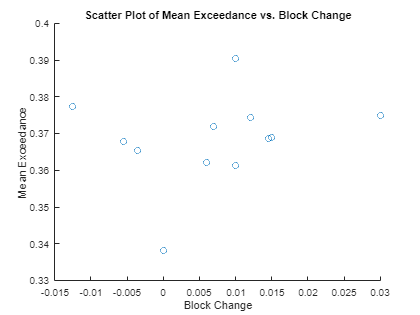


figure;
scatter(dataTable.block_change, dataTable.meanExceedance);
xlabel(getDescription('block_change'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Block Change');

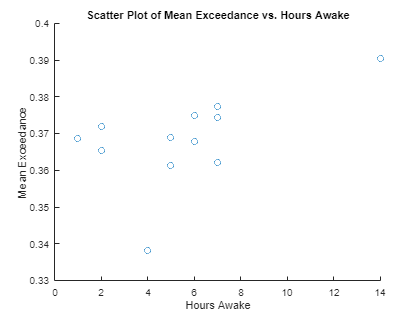


figure;
scatter(dataTable.hoursAwake, dataTable.meanExceedance);
xlabel(getDescription('hoursAwake'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Hours Awake');

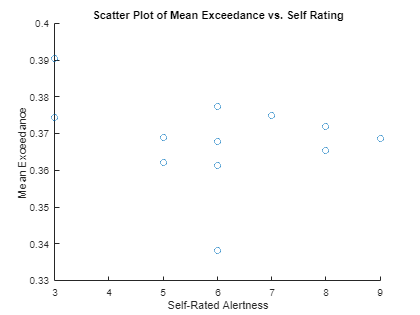


figure;
scatter(dataTable.selfRating, dataTable.meanExceedance);
xlabel(getDescription('selfRating'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Self Rating');

function description = getDescription(variable)

% Define a cell array with the variable names and their descriptions
variableDescriptions = {
    'omission_n', 'Number of Omissions';
    'omission_percent', 'Percentage of Omissions';
    'omission_percentile', 'Omission Percentile';
    'comission_n', 'Number of Commissions';
    'comission_percent', 'Percentage of Commissions';
    'comission_percentile', 'Commission Percentile';
    'rt_ms', 'Reaction Time (ms)';
    'rt_percentile', 'Reaction Time Percentile';
    'rt_se_ms', 'Reaction Time Standard Error (ms)';
    'rt_se_percentile', 'Reaction Time Standard Error Percentile';
    'variability', 'Variability';
    'detectibility', 'Detectability';
    'responose_style', 'Response Style';
    'perservation_n', 'Number of Perservations';
    'perservation_percentile', 'Perservation Percentile';
    'block_change', 'Block Change';
    'block_change_se', 'Block Change Standard Error';
    'isi_change', 'Inter-Stimulus Interval Change';
    'isi_change_se', 'Inter-Stimulus Interval Change Standard Error';
    'meanFixation', 'Mean Fixation Duration';
    'varFixation', 'Fixation Duration Variability';
    'numFixationPerMin', 'Number of Fixations per Minute';
    'meanExceedance', 'Mean Exceedance';
    'varExceedance', 'Exceedance Variability';
    'detrendedVarExceedance', 'Detrended Exceedance Variability';
    'hoursAwake', 'Hours Awake';
    'selfRating', 'Self-Rated Alertness'
    'ExceedanceAvgPeakHeight', 'Average Exceedance Peak Height';
    'ExceedanceAvgCorrectionTime','Average Pilot Exceedance Correction';
    'ExceedanceEntropy', 'Exceedance Signal Entropy';
};
    descriptionRow = strcmp(variableDescriptions(:, 1), variable);
    
    if any(descriptionRow)
        description = variableDescriptions{descriptionRow, 2};
    else
        description = variable; % If no description is found, return the original variable name
    end
end


